# Longitudinal Vehicle - Main Script

## Harness Model

A harness model is used to test the main component, which is **Longitudinal Vehicle** referenced subsystem.

 
mdl = "Vehicle1D_harness_model";
open_system(mdl)

refsub_type = "Driveline";
% refsub_type = "Custom";

refsub = "Vehicle1D_refsub_" + refsub_type

refsub = "Vehicle1D_refsub_Driveline"


% Load model parameters.
Vehicle1D_harness_setup

% Set referenced subsystem.
set_param(mdl + "/Longitudinal Vehicle", ...
  ReferencedSubsystem = refsub)

% Update model for a screenshot.
set_param(mdl, SimulationCommand = "update")

imgFolder = fullfile( currentProject().RootFolder, ...
              "Components", "Vehicle1D", "images" );

% Take screenshot, save, and show it.
mdlFileName = mdl + ".mdl";
mdlFilePath = findFilesFromProject(mdlFileName);
imgFileName = "image_" + mdl + ".png";
imgFilePath = findFilesFromProject(imgFileName);
if isNewerFileDateTime(mdlFilePath, imgFilePath)
  disp("Taking a screenshot image.")
  result = screenshotSimulink( ...
              SimulinkModelName = mdl, ...
              SaveFolder = imgFolder );
else
  disp("Using an existing image.")
end

Taking a screenshot image.


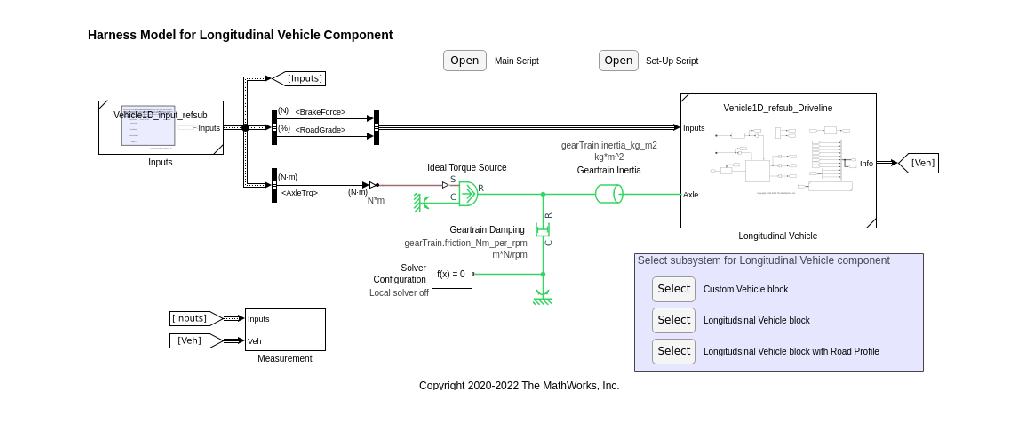

imshow(imgFilePath)

## Vehicle Component Subsystem

This subsystem is the main component under test. This is also used in a system-level model.

imgFileName = "image_" + refsub + ".png";
imgFilePath = findFilesFromProject(imgFileName);
if isNewerFileDateTime(mdlFilePath, imgFilePath)
  disp("Taking a screenshot image.")
  result = screenshotSimulink( ...
              OutputFileName = imgFileName, ...
              SimulinkModelName = mdl, ...
              SubsystemPath = "/Longitudinal Vehicle", ...
              SaveFolder = imgFolder );
else
  disp("Using an existing image.")
end

Taking a screenshot image.


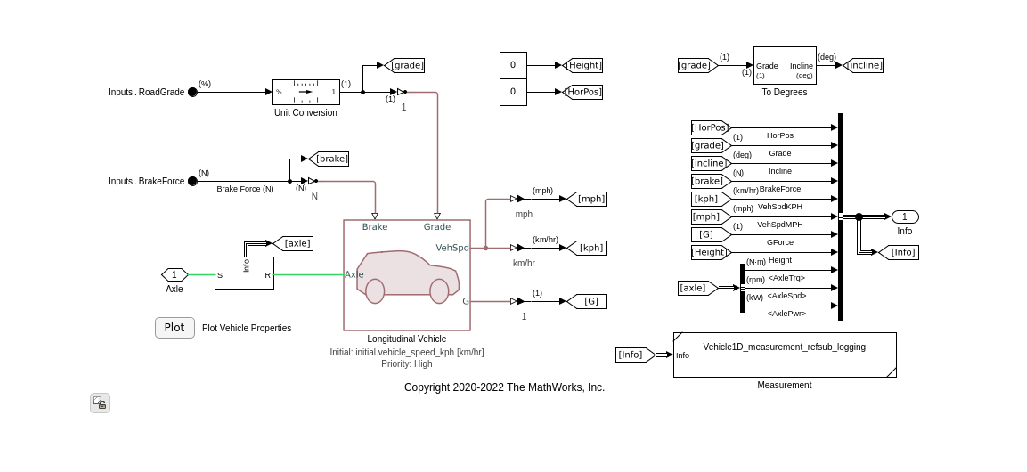

imshow(imgFilePath)

## Vehicle Properties - Resisting Force and Power

These plots represent the basic properties of the vehicle component.

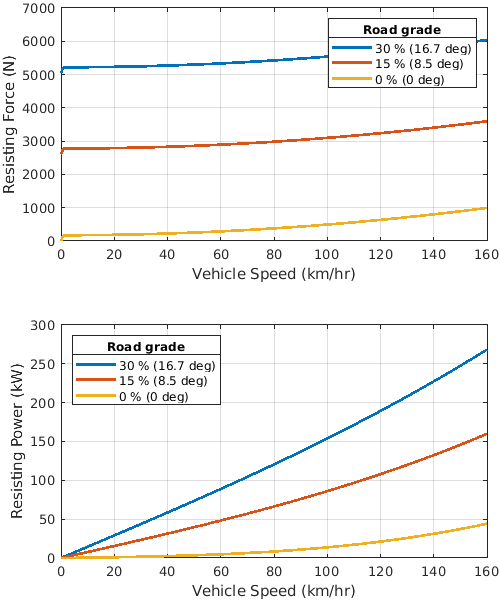

% Select subsystem.
set_param(0, CurrentSystem = mdl + "/Longitudinal Vehicle")

% Select block.
set_param(gcs, CurrentBlock = "Longitudinal Vehicle")

% Collect block parameters.
switch refsub_type
case "Driveline"
  block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);
case "Custom"
  block_info = Vehicle1DUtility.getVehicle1DCustomBlockInfo(gcbh);
end

fig = Vehicle1DUtility.plotRoadLoad( ...
        VehicleMass_kg = block_info.M_e_kg, ...
        RoadLoadA_N = block_info.A_rl_N, ...
        RoadLoadB_N_per_kph = block_info.B_rl_N_per_kph, ...
        RoadLoadC_N_per_kph2 = block_info.C_rl_N_per_kph2, ...
        GravitationalAcceleration_m_per_s2 = block_info.grav_m_per_s2, ...
        VehicleSpeedVector_kph = linspace(0, 160, 200), ...
        RoadGradeVector_pct = [30, 15, 0] );

fig.Position(3:4) = [500 600];  % Width height

imgPath = fullfile(imgFolder, "image_Vehicle1D_"+refsub_type+"_ResistingForcePower.png");

exportgraphics(fig, imgPath)

## Simulation

### Basic Check

This simple simulation checks that the model just runs.

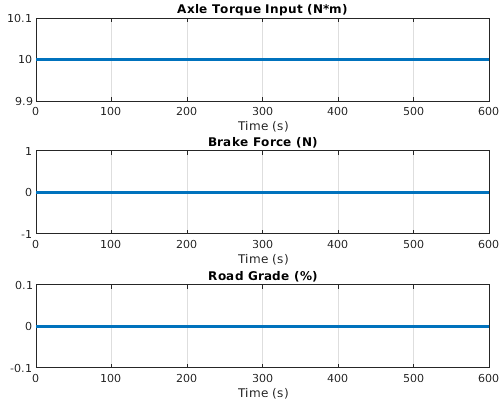

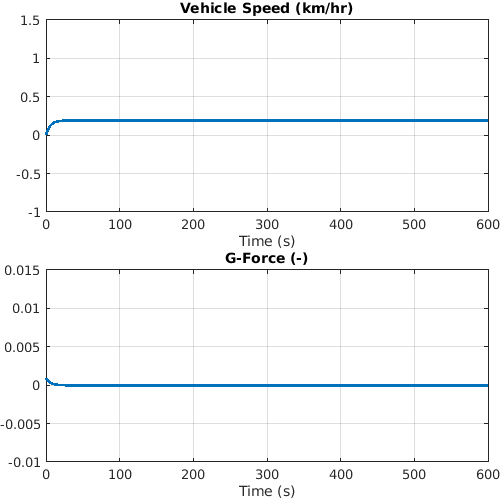

% External input signals
vehSigBuilder = Vehicle1D_InputSignalBuilder;

inpData = Constant(vehSigBuilder);

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setVariable(simIn, "initial.vehicle_speed_kph", ...
          inpData.Options.InitialVehicleSpeed_kph);

% Initial conditions
v0 = inpData.Options.InitialVehicleSpeed_kph;

simIn = setBlockParameter(simIn, ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x", num2str(v0), ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_unit", "km/hr", ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_priority", "high");

% Run simulation
simOut = sim(simIn);

Vehicle1D_plotResults(simOut.logsout)

finishRunningScript = true;
switch finishRunningScript
case true
  % The execution of this script stops here.
  return
end

### Coastdown

 
edit("Vehicle1D_testcase_Coastdown.mlx")

### Input Torque to Axle

 
edit("Vehicle1D_testcase_DriveAxle.mlx")

### Vary Braking Force

 
edit("Vehicle1D_testcase_Brake3.mlx")

### Vary Road Grade

 
edit("Vehicle1D_testcase_RoadGrade3.mlx")

*Copyright 2020-2022 The Mathworks, Inc.*